# Introduction: Root Locus Controller Design

In this tutorial, we will introduce the root locus plot and demonstrate how to generate the plot with MATLAB, as well as how to use MATLAB to design feedback controllers that satisfy certain performance criteria through the use of the root locus. 

Key MATLAB commands used in this tutorial are: [`feedback`](http://www.mathworks.com/help/toolbox/control/ref/feedback.html) ,  [`rlocus`](http://www.mathworks.com/help/control/ref/rlocus.html) ,  [`step`](http://www.mathworks.com/help/toolbox/control/ref/step.html) 

## Root Locus Concept

The root locus of a feedback system is a plot of the locations (locus) of all possible closed-loop poles with some parameter, often a proportional gain $K$, varied between $0$ and $\infty$. The figure below shows a unity-feedback architecture, but the procedure is identical for any open-loop transfer function $H(s)$, even if some elements of the open-loop transfer function are in the feedback path.

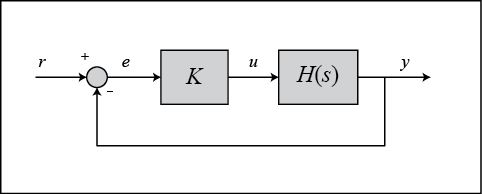

Let us consider the given unity-feedback system with:


$$
H(s) = \frac{Y(s)}{U(s)} = \frac{s + 2}{s^2+2s+3}
$$


The following live script first plots the open-loop poles and zeros with blue X's and O's, respectively. Then as you move the slider to vary the value of the proportional gain $K$, it adds points to the figure representing the system's closed poles for each specific value of $K$. As you plot more and more values of the parameter, you can imagine connecting the dots to generate a continuous graph. Such a figure containing the closed-loop poles for all values of $K$ from $0$ to $\infty$ is a root locus plot. If you would like to clear the figure, you can choose the selection "reset figure" from the drop-down menu. If you then return to the "hold figure" selection, you can again see the different closed-loop pole locations as $K$ is varied with the slider.

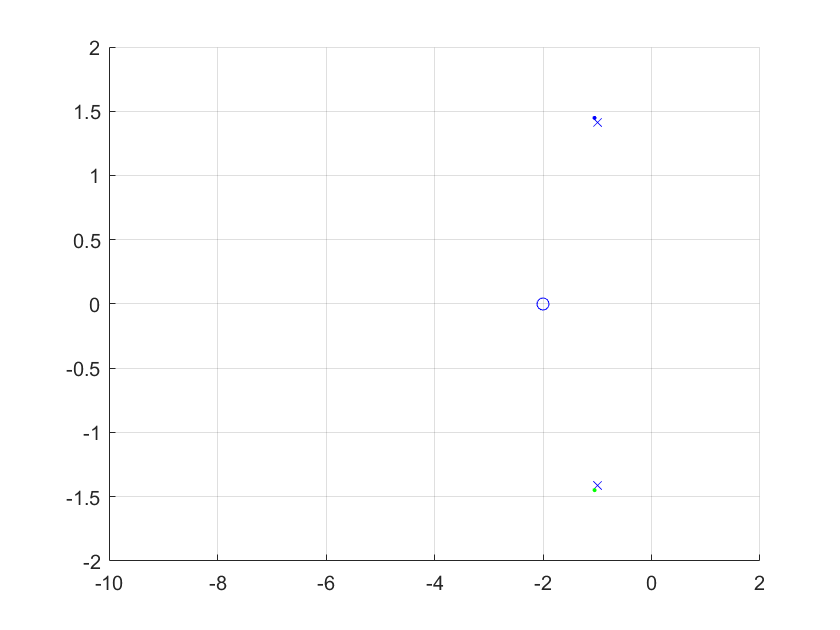

figure(1);hold on;
s = tf('s');
H = (s+2)/(s^2 + 2*s + 3);
z_ol = zero(H);
p_ol = pole(H);
axis([-10 2 -2 2])
grid on
hold on
plot(real(z_ol),imag(z_ol),'bO')
plot(real(p_ol),imag(p_ol),'bX')
K = 0.1;
T = feedback(K*H,1);
p_cl = pole(T);
realpart = real(p_cl);
imagpart = imag(p_cl);
if ~isempty(realpart) || ~isempty(imagpart)
    plot(realpart(1),imagpart(1),'b.',realpart(2),imagpart(2),'g.')
end

It is interesting to note where the closed-loop poles are located when $K$ equals zero and what they approach as $K$ increases toward $\infty$. If you employ the MATLAB command `rlocus`, a figure is generated that connects all points for $K$ equals zero to infinity, as shown in the following: 

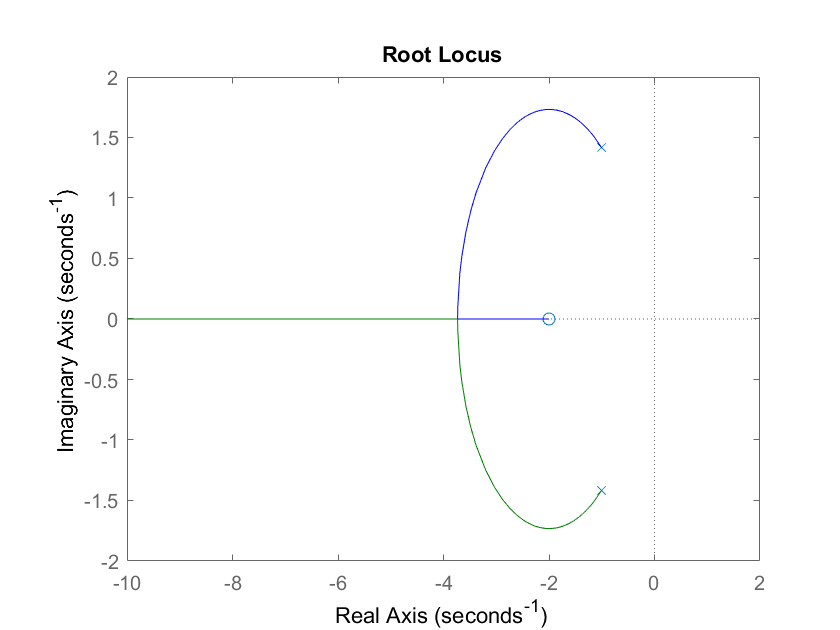

figure(2)
rlocus(H)
axis([-10 2 -2 2])

In the preceding section, the root locus plot was generated by brute force where the figure was plotted point-by-point. Examination of the closed-loop transfer function can help us understand some trends of how the branches of the root locus will behave as the parameter $K$ is varied from $0$ to $\infty$. The closed-loop transfer function in this case is:


$$
\frac{Y(s)}{R(s)} = \frac{KH(s)}{1 + KH(s)}
$$


and thus the poles of the closed-loop system are values of $s$ such that $1 + KH(s) = 0$.

If we write $H(s) = b(s)/a(s)$, then this equation can be rewritten as:


$$
\Rightarrow\ a(s) + Kb(s) = 0
$$



$$
\Rightarrow\ \frac{a(s)}{K} + b(s) = 0
$$


Let $n$ be the order of $a(s)$ and $m$ be the order of $b(s)$ (the order of the polynomial corresponds to the highest power of $s$).

We will consider all positive values of $K$. In the limit as $K \rightarrow 0$, the poles of the closed-loop system are solutions of $a(s) = 0$ (poles of $H(s)$). In the limit as $K \rightarrow \infty$, the poles of the closed-loop system are solutions of $b(s) = 0$ (zeros of $H(s)$).

No matter our choice of $K$, **the closed-loop system has** $n$** poles**, where $n$ is the number of poles of the open-loop transfer function $H(s)$.  **The root locus then has** $n$** branches**, each branch starts at a pole of $H(s)$ and approaches a zero of $H(s)$. If $H(s)$ has more poles than zeros (as is often the case), $m < n$ and we say that $H(s)$ has **zeros at infinity**. In this case, the limit of $H(s)$ as $s \rightarrow \infty$ is zero. The number of zeros at infinity is $n-m$, the number of open-loop poles minus the number of open-loop zeros, and is the number of branches of the root locus that go to "infinity" (asymptotes).

Since the root locus consists of the locations of all possible closed-loop poles, the root locus helps us choose the value of the gain $K$ to achieve the type of performance we desire. If any of the selected poles are on the right-half complex plane, the closed-loop system will be unstable. The poles that are closest to the imaginary axis have the greatest influence on the closed-loop response, so even if a system has three or four poles, it may still behave similarly to a second- or a first-order system, depending on the location(s) of the dominant pole(s).

Notice that in the preceding case there are more poles than zeros ($m < n$) and therefore there is a zero at infinity. Using the slider to slowly increase $K$ demonstrates how the closed loop poles start at the open loop poles (X) moved towards the zero (O) and a zero at infinity (towards -$\infty$ along the real axis).

## Choosing a Value of K from the Root Locus

Consider an open-loop system which has the following transfer function.


$$
H(s) = \frac{Y(s)}{U(s)} = \frac{s + 7}{s(s + 5)(s + 15)(s + 20)}
$$


How do we design a feedback controller for the system using the root-locus method? Let's assume our design criteria are a maximum overshoot of 5% and a rise time of 1 second. Create an [m-file](http://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_Mfile) titled `rl.m`. Within this file, create the transfer function model and employ the `rlocus` command as follows:

sys = (s + 7)/(s*(s + 5)*(s + 15)*(s + 20));
rlocus(sys)
axis([-22 3 -15 15])

The plot just generated shows all possible closed-loop pole locations for a pure proportional controller. In this case, not all of these closed-loop pole locations indicate satisfaction of our design criteria. To determine what part of the locus is acceptable, we can use the command `sgrid(zeta,wn)` to plot lines of constant damping ratio and natural frequency. Its two arguments are the damping ratio ($\zeta$) and natural frequency ($\omega_n$) [these may be vectors if you want to look at a range of acceptable values]. In our problem, we need an overshoot less than 5% (which means a damping ratio $\zeta$ of greater than 0.7) and a rise time less than 1 second (which means a natural frequency $\omega_n$ greater than 1.8). Enter the following in the MATLAB command window:

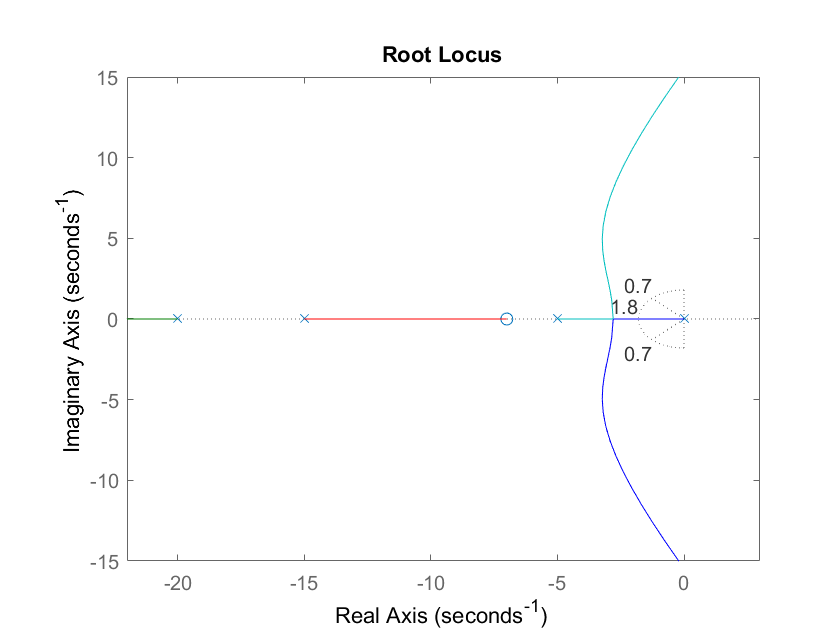

zeta = 0.7;
wn = 1.8;
sgrid(zeta,wn)

On the plot above, the two dotted lines at about a 45-degree angle indicate pole locations with $\zeta$ = 0.7; in between these lines, the poles will have $\zeta$ > 0.7 and outside of these lines $\zeta$ < 0.7. The semicircle indicates pole locations with a natural frequency $\omega_n$ = 1.8; inside of the circle $\omega_n$ < 1.8 and outside of the circle $\omega_n$ > 1.8.

Going back to our problem, to make the overshoot less than 5%, the poles have to be in between the two angled dotted lines and to make the rise time shorter than 1 second, the poles have to be outside of the dotted semicircle. So now we know what part of the root locus, which possible closed-loop pole locations, satify the given requirements. All the poles in this region are in the left-half plane, so the closed-loop system is guaranteed to be stable.

From the plot above we see that there is part of the root locus inside the desired region. Therefore, in this case, we need only a proportional controller to move the poles to the desired region. You can use the `rlocfind` command in MATLAB to choose the desired poles on the locus:

`[k,poles] = rlocfind(sys)`

Click the point on the plot where you want a closed-loop pole to be. You may want to select one of the points indicated in the plot below to satisfy the design criteria.

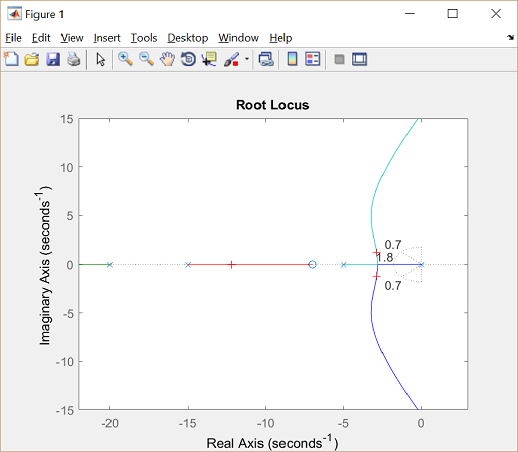

Note that since the root locus may have more than one branch, when you select a pole, you also identify where other closed-loop poles are too, all for the same corresponding value of $K$. Remember that these poles will affect the response too. From the plot above, we see that of the four poles selected (indicated by "+" signs), the two closest to the imaginary axis are in our desired region (one resulting closed-loop pole cannot be seen in the figure, it is off to the left and is located on the real axis). Since these poles tend to dominate the response, we have some confidence that our desired requirements will be met for a proportional controller with this value of $K$.

Since our closed-loop system does not have the form of a canonical second-order system, we will need to verify that our requirements are met by examining the closed-loop system's the step response. One can first compute the closed-loop transfer function using the rules of block diagram reduction, or we can employ MATLAB (there is no need to enter a value for `K` if the `rlocfind` command was used):

K = 350;
sys_cl = feedback(K*sys,1)

sys_cl =
 
               350 s + 2450
  --------------------------------------
  s^4 + 40 s^3 + 475 s^2 + 1850 s + 2450
 
Continuous-time transfer function.



The two arguments to the function `feedback` are the transfer function in the forward path and the transfer function in the feedback path of the open-loop system. In this case, our system is unity feedback. If you have a non-unity feedback situation, look at the help file for the MATLAB function `feedback`.

Checking the step response of the closed-loop system with the chosen value of $K$:

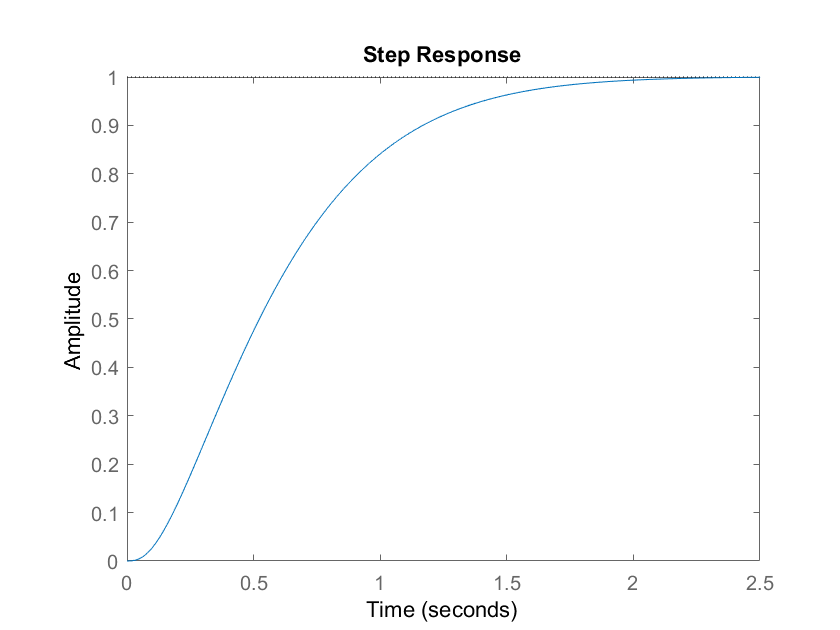

step(sys_cl)

As we expected, this response has an overshoot less than 5% and a rise time less than 1 second.

## Design with the Root Locus

In the preceding, our initial choice of gain $K$ was able to meet the given design requirements. It is sometimes the case that we must iterate on our design to meet the requirements. The root locus is helpful in this regard since it demonstrates how the closed-loop poles move as the parameter $K$ is varied. Specifically, we would recall how the dominant second-order (or first-order) poles relate to a system's step response. With the following script, you can use the live control to vary the control gain $K$ and observe how the system's three closed-loop poles (marked by black squares) move from the open-loop poles toward the open-loop zeros as $K$ is increased. The resulting plot additionally shows the closed-loop step response that corresponds to the chosen value $K$. For example, consider what happens to the step response when the dominant closed-loop poles are outside of the 45 degree lines ($\zeta$ < 0.7) and/or inside the circle ($\omega_n$ < 1.8). Are the design criteria met?

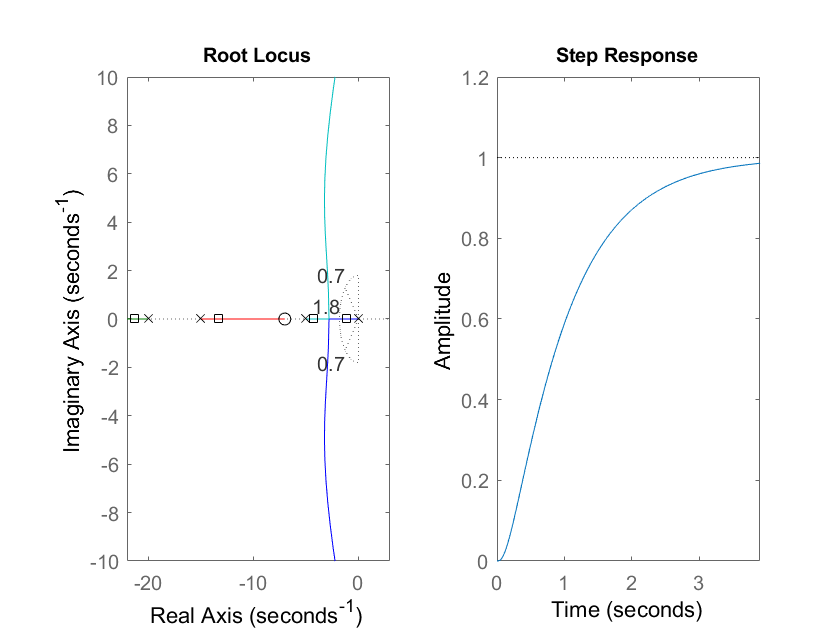

K = 300;
sys = (s + 7)/(s*(s + 5)*(s + 15)*(s + 20));
figure(3)
subplot(1,2,2)
subplot(1,2,1)
rlocus(sys)
hold on
rlocus(sys,K,'ks')
axis([-22 3 -10 10])
zeta = 0.7;
wn = 1.8;
sgrid(zeta,wn)
subplot(1,2,2)
T = feedback(K*sys,1);
step(T)
axis([0 3.9 0 1.2])

In this case, we were able to meet the design requirements with a simple proportional controller. That is, we were able to move the dominant closed-loop poles into the desired region of the complex plane by varying $K$. If that were not the case, we would need to re-shape the root locus by adding poles and/or zeros via the controller.